# Actividad #10

#### Fecha: 28/06/2024

#### Objetivos:

- Git: **Discard All Changes in Repository**

- Crear funciones : fPlot.m

- Usar matrices de 3 dimnesiones (muestras, variables, clientes)

- Cambio de clientes con controles para mostrar datos

#### Nombre:

- sunombre

#### Repository:

- [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

#### Librarys:

- [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- [https://es.mathworks.com/help/matlab/ref/ls.htm](https://es.mathworks.com/help/matlab/ref/ls.htm)

- [https://es.mathworks.com/help/matlab/ref/matlab.git.gitrepository.discardchanges.html#d126e406558](https://es.mathworks.com/help/matlab/ref/matlab.git.gitrepository.discardchanges.html#d126e406558)

## Paso 0: Descartar cualquier cambio realizado en el repositorio clonado

%Version Online, Opcion 1:
% Source Control -> Discard all changes
% Source Control -> git pull

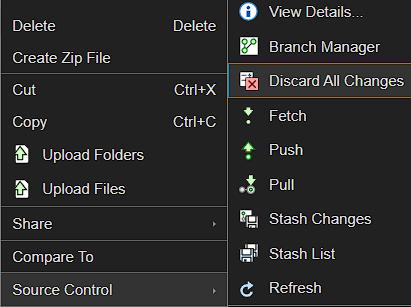

%Version Online, Opcion 2:
% repo = gitrepo;
% discardChanges(repo,repo.ModifiedFiles);
% Source Control -> git pull

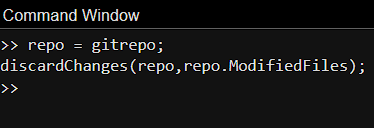

% Version para PC, en el Bash del Git:
% git status
% git reset --hard
% Git pull

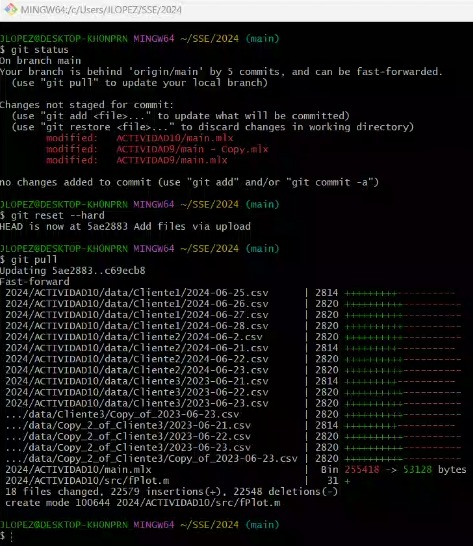

## Paso 1: Limpiar variables y linea de comandos

clear % Para borrar el workspace y liberar memoria RAM
clc  % Limpiar el command window
raiz = cd;%Linux: Addres Current folder

## Paso 2.- Configuración de carpeta ./src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

## **Paso 3- Configuranción de carpeta de ./data para datasets**

%Nombre de la carpeta donde estan los archvios csv
datapath=fullfile('./data/');

## **Paso 4- Buscar los nombres y **Cargar los datos **de todos los archivos dentro de la carpeta ./data**

%Nombre de la carpeta donde estan los archvios csv

%Obtener los nombres de las carpetas
% Se asume que solo hay carpetas
cd(datapath); %Matlab: Acceder a la carpeta llamada del data
FolderNames=ls; %Linux: enlista todos las carpetas y archivos

%-----------Solo para la version online----------------
%FolderNames=split(FolderNames); %Cmabia un string a un vector de celadas
%FolderNames=string(FolderNames); %Cmabia un string a un vector de celadas
%------------------------------------------------------

cd(raiz);% "cd .." return to initial current folder

FolderNames=FolderNames(3:size(FolderNames,1),:);%Elimina ".", ".."
%-----------Solo para la version online----------------
%FolderNames=FolderNames(1:size(FolderNames,1)-1,:);%Elimina " " que esta al final
%------------------------------------------------------

%AllData=NaN(5628,5,size(FolderNames,1));%Analizarlo NaN
AllData=[];

for i=1:1:size(FolderNames,1) %# de filas = # de carpetas
    names=FindCSV(fullfile(datapath,FolderNames(i,:)));
    %filenames=[filenames struct2table(names).name];

    newPath=strcat(fullfile(datapath,FolderNames(i,:)),'\');
    %-----------Solo para la version online----------------
    %newPath=strcat(fullfile(datapath,FolderNames(i,:)),'/');
    %------------------------------------------------------

    AllData(:,:,i)= fLoadCSV(names,newPath);
end

clear names newPath FolderNames i;

## Paso 5: Set de Nombres de variables and Max Values

Es importante que el archivo csv se encuentre en la misma carpeta que el main

%Estos son los nombres de las variables
vname=["Corriente","Voltaje","variable3","variable4","variable5"];
MaxColumnas=size(AllData,2);
MaxFilas=size(AllData,1);
MaxClient=size(AllData,3);

## Paso 6: Graficar el dataset

Seleccionar el numero de variables a mostrar


nvar=5;
nfilas=10;
Cliente=4;

## Paso 7: Personalizar las graficas con los EstilosLinea

LinK: [https://es.mathworks.com/help/matlab/ref/plot.html](https://es.mathworks.com/help/matlab/ref/plot.html)

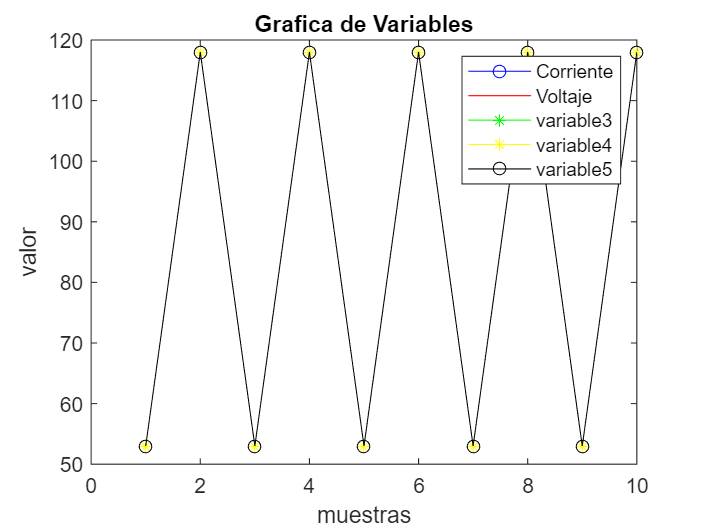

%Se limita la cantidad de filas y columnas a graficar x cliente
DatosPlot=AllData(1:nfilas,1:nvar,Cliente);
EstilosLinea=["-ob","-r","-*g","-*y","-ok"];

%EstilosLinea=string(['--b';'--r';'-*y';'-ok']);%Version2

fPlot(DatosPlot,vname,EstilosLinea);